# Solve Linear System with Infinite Solutions

Solve a linear system that has infinitely many solutions with backslash (`\`) and `lsqminnorm`. Compare the results using the 2-norms of the solutions.

When infinite solutions exist to $\mathrm{Ax}=b$, each of them minimizes $\left\|\mathrm{Ax}-b\right\|$. The backslash command (`\`) computes one such solution, but this solution typically does not minimize $\left\|x\right\|$. The solution computed by `lsqminnorm` minimizes not only `norm(A*x-b)`, but also `norm(x)`.

Consider a simple linear system with one equation and two unknowns, $2x_1 +3x_2 =8$. This system is *underdetermined* since there are fewer equations than unknowns. Solve the equation using both backslash and `lsqminnorm`.

A = [2 3];
b = 8;
x_a = A\b

x_b = lsqminnorm(A,b)

The two methods obtain different solutions because backslash only aims to minimize `norm(A*x-b)`, whereas `lsqminnorm` also aims to minimize `norm(x)`. Calculate these norms and put the results in a table for easy comparison.

s1 = {'Backslash'; 'lsqminnorm'};
s2 = {'norm_Ax_minus_b','norm_x'};
T = table([norm(A*x_a-b); norm(A*x_b-b)],[norm(x_a); norm(x_b)],'RowNames',s1,'VariableNames',s2)

This figure illustrates the situation and shows which solutions each of the methods return. The blue line represents the infinite number of solutions to the equation $x_2 =-\frac{2}{3}x_1 +\frac{8}{3}$. The orange circle represents the minimum distance from the origin to the line of solutions, and the solution returned by `lsqminnorm` lies exactly at the tangent point between the line and circle, indicating it is the solution that is closest to the origin.

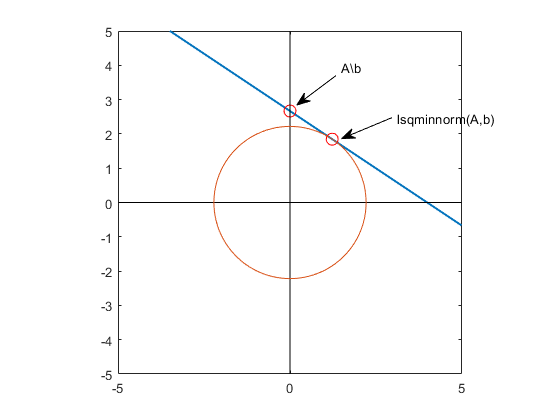

*Copyright 2012 The MathWorks, Inc.*